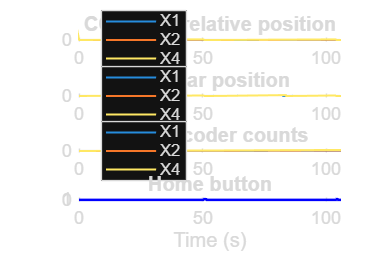

S = load('C:\Users\Admin\Desktop\RMX\Lab\encoder\data.mat');

name = 'CCWD_1'; % CWD_1, CCWD_1, CWU_1 หรือ CCWU_1
ds = S.(name);

% จำนวน count ต่อรอบของ X1 — ให้ตรงกับที่ตั้ง Encoder จริง
if contains(name,'U')
    N = 2048; % AMT103-V
else
    N = 24;   % BOURNS
end

rawIdx   = [5 6 7];    % Raw X1, X2, X4
countIdx = [9 13 11];  % Relative count X1, X2, X4
angleIdx = [8 12 10];  % มุม X1, X2, X4

raw = [];
relative = [];
angle = [];

for j = 1:3
    sig = getElement(ds,rawIdx(j));
    t = sig.Values.Time(:);
    raw(:,j) = double(sig.Values.Data(:));

    sig = getElement(ds,countIdx(j));
    relative(:,j) = double(sig.Values.Data(:));

    sig = getElement(ds,angleIdx(j));
    angle(:,j) = double(sig.Values.Data(:));
end

% Homing จากบล็อก Constant
sig = getElement(ds,1);
homeTime = sig.Values.Time(:);
homeData = double(sig.Values.Data(:));

% ขยาย Homing ให้ตรงกับเวลาของตัวนับ
[homeTime,idx] = unique(homeTime,'last');
homeData = homeData(idx);

if numel(homeTime) == 1
    home = repmat(homeData,size(t));
else
    home = interp1(homeTime,homeData,t,'previous','extrap');
end

figure('Color','w','Position',[100 50 1200 950]);
tiledlayout(4,1,'TileSpacing','compact');

ax(1) = nexttile;
stairs(t,relative,'LineWidth',1.2);
grid on;
ylabel('Relative count');
legend('X1','X2','X4','Location','best');
title([name ': relative position'],'Interpreter','none');

ax(2) = nexttile;
stairs(t,angle,'LineWidth',1.2);
grid on;
ylabel('Angle (deg)');
legend('X1','X2','X4','Location','best');
title('Angular position');

ax(3) = nexttile;
stairs(t,raw,'LineWidth',1.2);
grid on;
ylabel('Raw count');
legend('X1','X2','X4','Location','best');
title('Raw encoder counts');

ax(4) = nexttile;
stairs(t,home,'B','LineWidth',1.5);
grid on;
ylim([-0.1 1.1]);
yticks([0 1]);
ylabel('Homing State');
xlabel('Time (s)');
title('Home button');

linkaxes(ax,'x');
xlim(ax(1),[t(1) t(end)]);
set(ax,'FontSize',11);


% ความเร็วเฉลี่ยจาก X1 ดิบที่แก้ rollover
% ไม่ได้รับผลจากการตั้งศูนย์ใน Relative count
delta = mod(diff(raw(:,1))+32768,65536)-32768;
continuousCount = [0; cumsum(delta)];

% ใช้ช่วงระหว่างขอบขาขึ้นของ Home
homeEdges = find(diff(home > 0) == 1)+1;

if numel(homeEdges) >= 2
    starts = homeEdges(1:end-1);
    stops  = homeEdges(2:end);
else
    % หากมี Home ไม่ครบสองครั้ง ใช้ช่วงบันทึก
    % เริ่ม sample ที่สองเพื่อข้ามค่าเริ่มต้นตอนเปิดการบันทึก
    starts = 2;
    stops = numel(t);
end

duration = t(stops)-t(starts);
displacement = (continuousCount(stops)-continuousCount(starts))*360/N;
omega = displacement./duration;
rpm = omega/6;

result = table(t(starts),t(stops),duration,displacement, ...
    omega,abs(omega),rpm, ...
    'VariableNames',{'Start_s','End_s','Duration_s', ...
    'Displacement_deg','Mean_deg_s','SpeedMagnitude_deg_s','Mean_RPM'});

disp(name);

CCWD_1


disp(result);

    Start_s    End_s     Duration_s    Displacement_deg    Mean_deg_s    SpeedMagnitude_deg_s    Mean_RPM
    _______    ______    __________    ________________    __________    ____________________    ________

     50.57     103.93      53.358            540             10.12              10.12             1.6867 

